clear;
a = readtable('result/data1.xlsx');
b = readtable('result\disaster_counts_by_year_and_type.csv');

c = readtable('result\disaster_counts_by_year.csv');

d = vertcat(a{2,1:20})

d = 1.0e+09 *

    0.2006    0.4053    0.6139    0.8340    1.0658    1.3083    1.5608    1.8241    2.0910    2.3572    2.6407    2.9358    3.2361    3.5431    3.8517    4.1581    4.4655    4.7787    5.1011    5.4243


e = vertcat(b{1:20,1:16})'

e =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     1     0     0     1     0     1     2     0     0     0     2     0     0     0     0     0     0     0
    25    22    24    14    11    20     9    11    16    18    21    16    18     9    20    27    14    12    17    15
    30    25    37    40    42    25    24    21    23    22    24    30    27    29    26    23    30    22    20    31
   113    69   112    32    43    56    54    35    41    44    44    24    25    23    23    14    25    27    16    37
    30    23    15    25    16    40    14    25    16    20    28    15    52    13    17    12    12    10    27    21
   157   156   171   158   128   191   226   217   165   151   184   156   136   148   137   161   159   127   128   195
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    

f = vertcat(c{1:20,2})'

f =    523   446   533   392   405   497   446   448   402   384   441   356   372   353   348   398   349   371   336   441


X = [d;e(13,:)]'

X = 1.0e+09 *

    0.2006    0.0000
    0.4053    0.0000
    0.6139    0.0000
    0.8340    0.0000
    1.0658    0.0000
    1.3083    0.0000
    1.5608    0.0000
    1.8241    0.0000
    2.0910    0.0000
    2.3572    0.0000


Y = e(16,:)'

Y =     0.6748
    0.8624
    0.9297
    0.8450
    0.7737
    0.8474
    0.8563
    1.0116
    0.7962
    0.9021


mdl = fitlm(X, Y);
y_pred = predict(mdl, X);
disp(mdl);

线性回归模型:
    y ~ 1 + x1 + x2

估计系数:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________

    (Intercept)       0.59659       0.19792     3.0143     0.0078124
    x1             1.1624e-10    1.7857e-11     6.5096    5.3461e-06
    x2             0.00094633     0.0018013    0.52535       0.60613


观测值数目: 20，误差自由度: 17
均方根误差: 0.127
R 方: 0.714，调整 R 方 0.681
F 统计量(常量模型): 21.2，p 值 = 2.38e-05


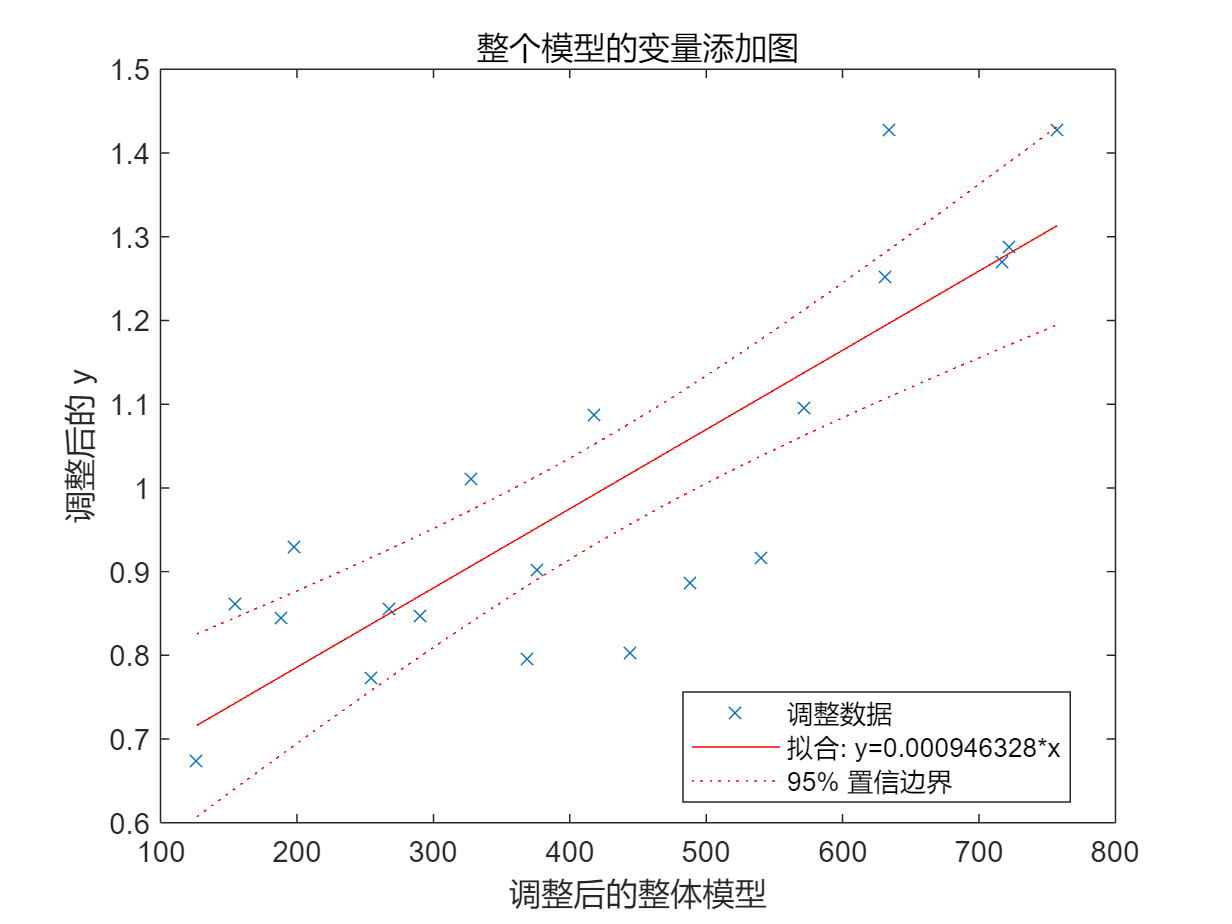

cla;
plot(mdl);

X = d;

Y = e(7,:);
p = polyfit(X, Y, 3);

y_fit = polyval(p, X);
disp(p)

    0.0000   -0.0000    0.0000  127.0108



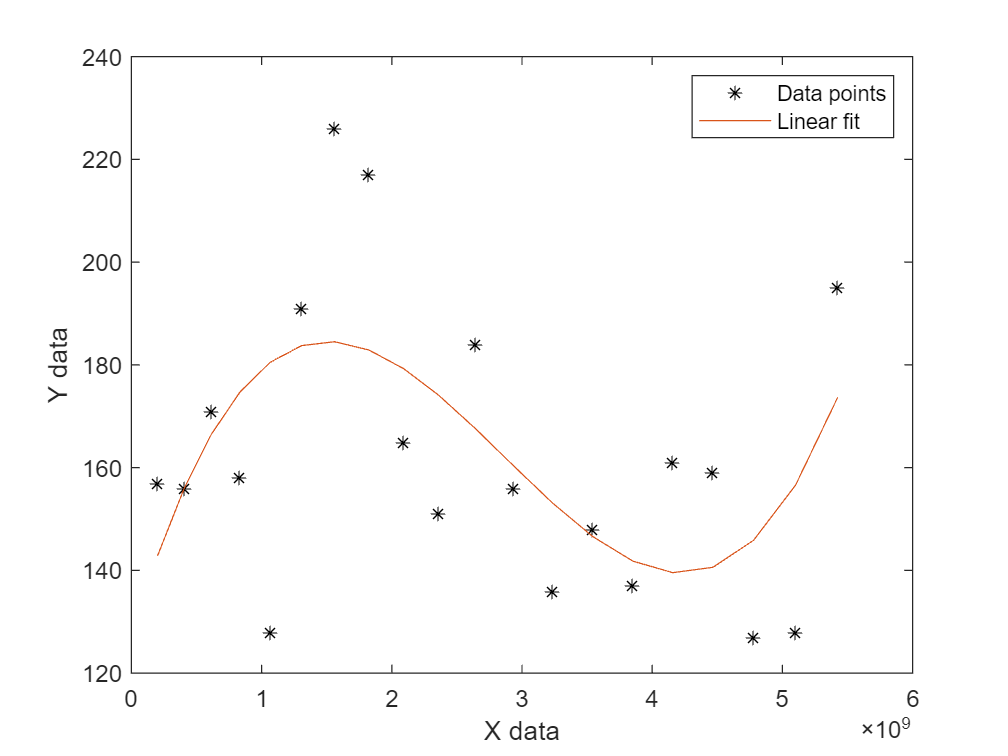

cla
plot(X, Y, '*k', X, y_fit, '-')
legend('Data points', 'Linear fit')
xlabel('X data')
ylabel('Y data')

X = e(16,:)

X =     0.6748    0.8624    0.9297    0.8450    0.7737    0.8474    0.8563    1.0116    0.7962    0.9021    1.0878    0.8040    0.8874    0.9172    1.0961    1.2530    1.4280    1.2699    1.2881    1.4276


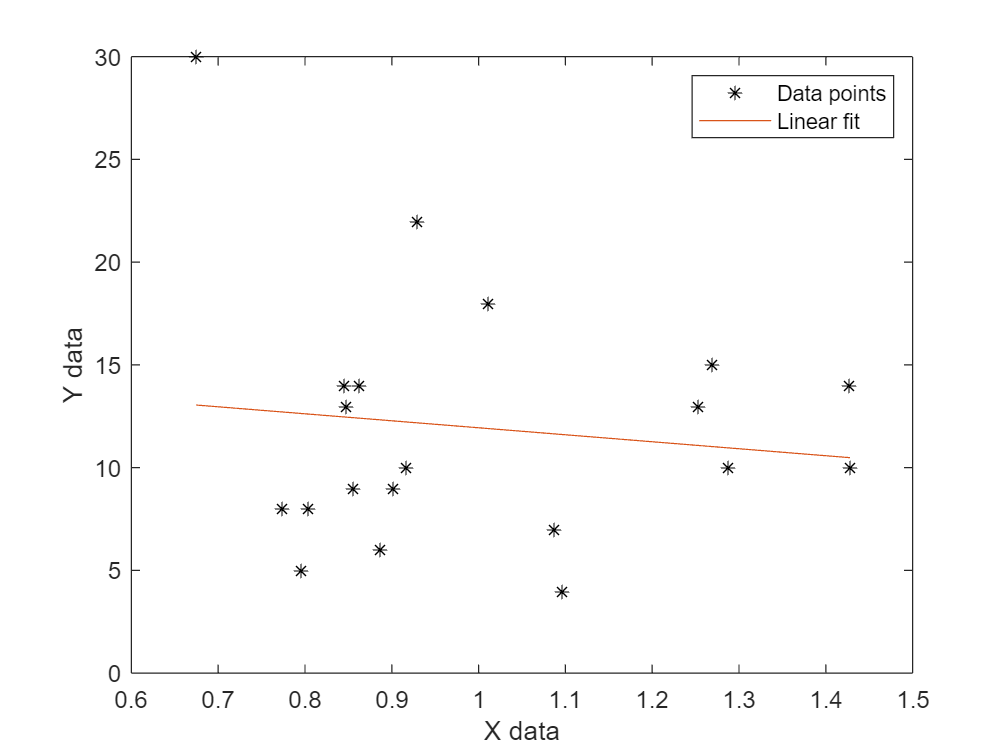

Y = e(15,:);
p = polyfit(X, Y, 1);
y_fit = polyval(p, X);

cla
plot(X, Y, '*k', X, y_fit, '-')
legend('Data points', 'Linear fit')
xlabel('X data')
ylabel('Y data')